## Fit bioluminescence and virus titers data with SCG model

Load experimental data

clear;clc;
biolu_data_ko = importdata('biolu_data_ko.txt');

Optimize using fminsearch

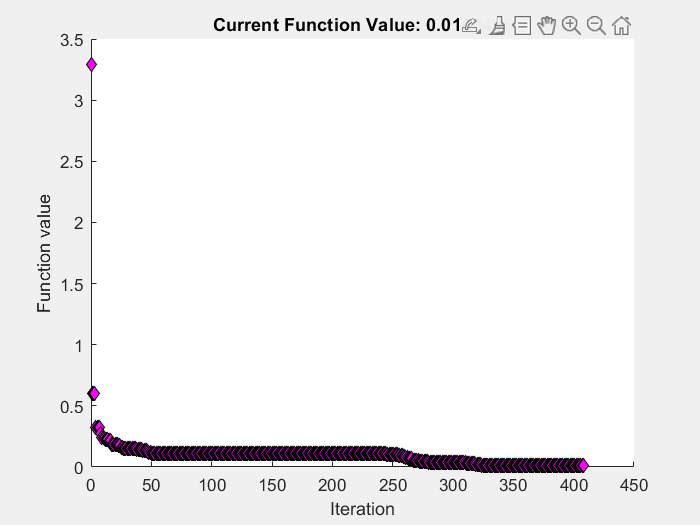

par_base = importdata('par_scg.txt');
par_base = par_base.data;
par_fit0 = par_base([1, 2, 6, 8]);
par_fix = par_base([3, 4, 5, 7]);

par_fit0(3) = log10(par_fit0(3));   % fit log value of p_tot

FitFcn = @(par_fit)Fit_err(biolu_data_ko, par_fit, par_fix);

options_fmin = optimset('PlotFcns',@optimplotfval);
[p, fminres] = fminsearch(FitFcn, par_fit0, options_fmin);

p(3) = 10 ^ p(3);
disp('tau_E tau_I p_tot c_B');

tau_E tau_I p_tot c_B


disp(p');

   1.0e+03 *

    0.0089    0.0146    9.2029    0.0001

